clear all;
close all;
clc;


run("C:\Users\33676\Documents\tictac\MATLAB\podometre\accelerometre1.m");  % Exécuter le script pour charger la variable acc

% === VALIDATION DES DONNÉES ===
disp('Vérification de l''intégrité des données...');

Vérification de l'intégrité des données...


if any(isnan(acc(:))) || any(isinf(acc(:)))
    error('Les données contiennent des valeurs manquantes ou infinies.');
else
    disp('Données OK');
end

Données OK


`Traitement des données de l’accéléromètre `

        Afin de traiter et d’exploiter efficacement les données issues de l’accéléromètre MPU6050 de notre montre, nous avons choisi d’utiliser MATLAB, il offre une large gamme de fonctions dédiées à l’analyse du signal et adapté à notre besoin de détection de pas à partir de mesures d’accélération. 

`Acquisition des données de l’accéléromètre `

        Pour acquérir des données précises, nous avons en premier lieu défini le nombre de valeurs à enregistrer ainsi que la fréquence d'échantillonnage des signaux. Nous avons opté pour 1200 valeurs sur une durée de 30 secondes pour chacun des trois canaux de données de l’accéléromètre, chaque valeur étant codée sur 16 bits. Pour cela, nous avons adapté un exemple de démonstration fourni avec le module MPU6050 afin de générer une sortie au format CSV sur le port série du STM32, exploitable ensuite dans Excel ou MATLAB. Pour le traitement des données, nous avons privilégié l'utilisation de MATLAB. 

`Visualisation des axes bruts de l'accéléromètre `

        Cette figure ci-dessous montre les courbes temporelles des composantes X, Y et Z de l’accélération mesurée par le MPU6050. Elle permet de visualiser les mouvements sur chaque axe séparément et d'identifier les modèles liés à la marche. Durant les tests, nous avons effectué une marche naturelle, c’est-à-dire à une fréquence de pas régulière et normale. 

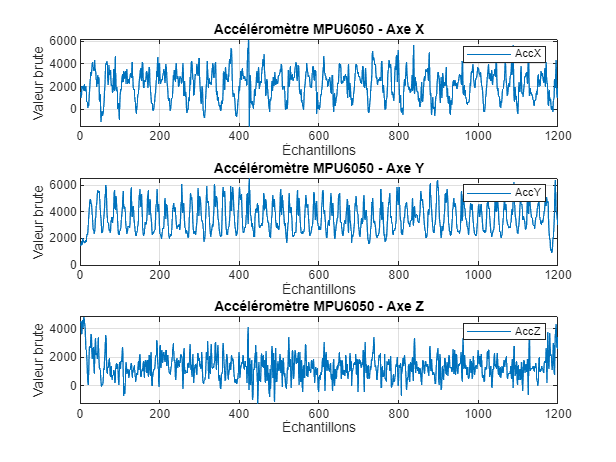

% === AFFICHAGE DES COURBES AccX, AccY, AccZ ===
figure;
subplot(3,1,1);
plot(acc(:,1));
legend('AccX');
xlabel('Échantillons');
ylabel('Valeur brute');
title('Accéléromètre MPU6050 - Axe X');
grid on;

subplot(3,1,2);
plot(acc(:,2));
legend('AccY');
xlabel('Échantillons');
ylabel('Valeur brute');
title('Accéléromètre MPU6050 - Axe Y');
grid on;

subplot(3,1,3);
plot(acc(:,3));
legend('AccZ');
xlabel('Échantillons');
ylabel('Valeur brute');
title('Accéléromètre MPU6050 - Axe Z');
grid on;


% === PARAMÈTRES ===
fs = 40;  % Fréquence d’échantillonnage en Hz

`Norme de l’accélération non filtrée  `

Ce graphique ci-dessous affiche la norme de l’accélération (racine carrée de la somme des carrés des trois axes). Il fournit une mesure globale de l’intensité du mouvement, indépendamment de l’orientation du capteur. 

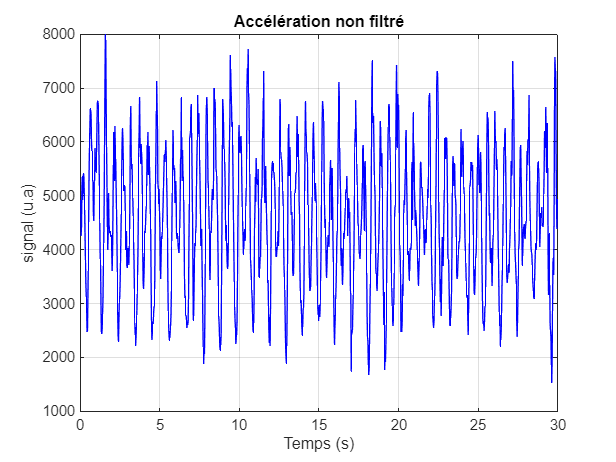

% === IMPORT DES DONNÉES ===
accX = acc(:,1); 
accY = acc(:,2);
accZ = acc(:,3);

% === CALCUL DE LA NORME DE L’ACCÉLÉRATION ===
accNorm = sqrt(accX.^2 + accY.^2 + accZ.^2);

% === AFFICHAGE DU SIGNAL ===
t = (0:length(accNorm)-1)/fs;
figure;
plot(t, accNorm, 'b');
xlabel('Temps (s)');
ylabel('signal (u.a)');
title("Accélération non filtré")
grid on;



% === FILTRAGE DU SIGNAL (axe X ici) ===
fc = [10*2/fs 60*2/fs];
ordre =1 ;
[b, a] = butter(ordre, fc/(fs/2), 'bandpass');
accFiltered = filtfilt(b, a, accNorm);


`Réponse en fréquence du filtre passe-bande `

Ce graphe ci-dessous présente le gain du filtre passe-bande (0.5–3 Hz) en normalisé, en fonction de la fréquence. Le filtre est conçu pour ne conserver que les fréquences associées à la marche humaine, tout en atténuant les autres bruits. 

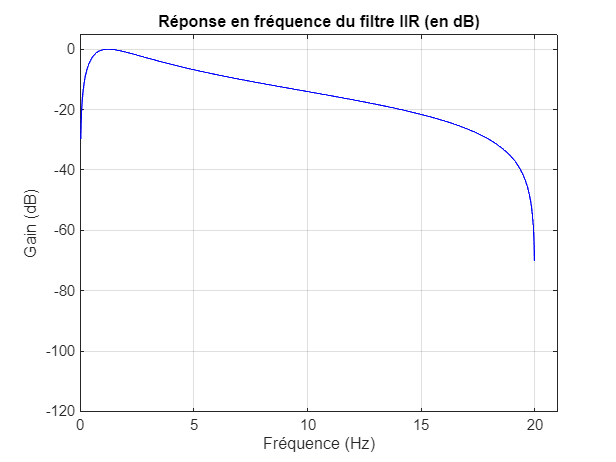


% === AFFICHAGE DE LA RÉPONSE EN FRÉQUENCE DU FILTRE ===
[Hf, Ff] = freqz(b, a, 1024, fs);  % 1024 points, Fe = fréquence d’échantillonnage
figure;
plot(Ff, 20*log10(abs(Hf)), 'b');
xlabel('Fréquence (Hz)');
ylabel('Gain (dB)');
title('Réponse en fréquence du filtre IIR (en dB)');
grid on;
xlim([0,21])
ylim([-120,5])

`Diagramme pôle-zéro du filtre `

Ce diagramme ci-dessous permet de vérifier la stabilité du filtre IIR utilisé. Tous les pôles sont à l’intérieur du cercle unité, ce qui confirme que le filtre est stable et adapté à une utilisation dans un système embarqué. 

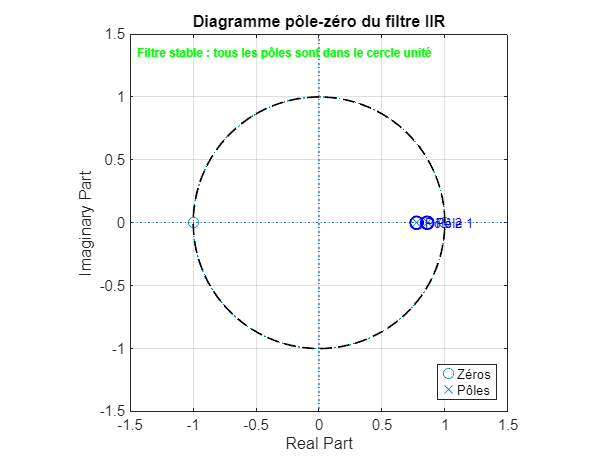


figure;
zplane(b, a);
title('Diagramme pôle-zéro du filtre IIR');
hold on;

% Cercle unité
theta = linspace(0, 2*pi, 1000);
h_cercle = plot(cos(theta), sin(theta), 'k--', 'LineWidth', 1.2);

% Récupération des pôles
poles = roots(a);

% Cercle autour de chaque pôle
for k = 1:length(poles)
    th = linspace(0, 2*pi, 100);
    r = 0.05;
    xc = real(poles(k)) + r*cos(th);
    yc = imag(poles(k)) + r*sin(th);
    h_p = plot(xc, yc, 'blue', 'LineWidth', 1.5);

    % Ne pas afficher ce cercle dans la légende
    set(get(get(h_p, 'Annotation'), 'LegendInformation'), 'IconDisplayStyle', 'off');
end


for k = 1:length(poles)
    text(real(poles(k)) + 0.07, imag(poles(k)), sprintf('Pôle %d', k), ...
        'FontSize', 9, 'Color', 'blue');
end

% Masquer le cercle unité de la légende
set(get(get(h_cercle, 'Annotation'), 'LegendInformation'), 'IconDisplayStyle', 'off');

% Sélectionner les objets affichés (pôles et zéros)
lines = findobj(gca, 'Type', 'line');
% Les deux premiers handles trouvés sont les zéros et pôles
% zéros = 'o', pôles = 'x'
zerosHandle = findobj(lines, 'Marker', 'o');
polesHandle = findobj(lines, 'Marker', 'x');

legend([zerosHandle(1), polesHandle(1)], {'Zéros', 'Pôles'}, 'Location', 'southeast');

% Ajustement de l’échelle
axis equal;
xlim([-1.5 1.5]);
ylim([-1.5 1.5]);
grid on;

% Vérification stabilité
if all(abs(poles) < 1)
    text(-1.45, 1.35, 'Filtre stable : tous les pôles sont dans le cercle unité', ...
         'Color', 'green', 'FontSize', 8, 'FontWeight', 'bold');
else
    text(-1.45, 1.35, 'Filtre instable : au moins un pôle est hors du cercle unité', ...
         'Color', 'red', 'FontSize', 8, 'FontWeight', 'bold');
end



% === DÉTECTION DES PICS (PAS) ===
threshold = 600;
minDist = round(0.4 * fs); 

[peaks, locs] = findpeaks(accFiltered, ...
    'MinPeakHeight', threshold, ...
    'MinPeakDistance', minDist);

nb_pas = length(peaks);


`Diagramme pôle-zéro du filtre `

Ce diagramme ci-dessous permet de vérifier la stabilité du filtre IIR utilisé. Tous les pôles sont à l’intérieur du cercle unité, ce qui confirme que le filtre est stable et adapté à une utilisation dans un système embarqué. 

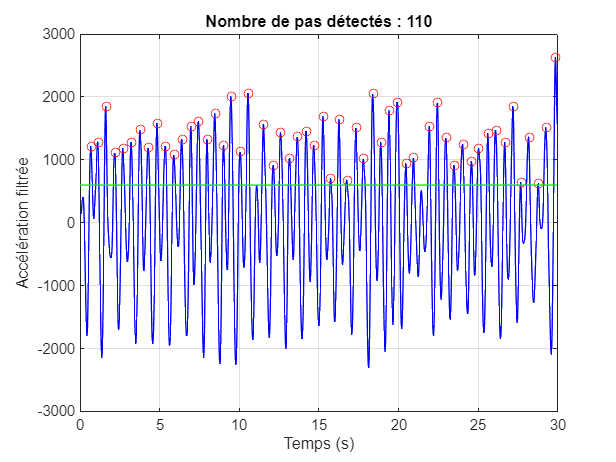


% === AFFICHAGE DU SIGNAL FILTRÉ ET DES PAS ===
t = (0:length(accNorm)-1)/fs;
figure;
plot(t, accFiltered, 'b');
hold on;
plot(locs/fs, peaks, 'ro');
plot(t, threshold * ones(size(t)), 'g'); % ligne verte pour le seuil
xlabel('Temps (s)');
ylabel('Accélération filtrée');
title(['Nombre de pas détectés : ', num2str(2 * nb_pas)]);
grid on;

`Spectre de Fourier du signal filtré `

Ce spectre ci-dessous met en évidence les composantes fréquentielles du signal filtré. Une annotation marque la fréquence fondamentale dominante, qui correspond au rythme de la marche. Cette fréquence est utilisée pour estimer la cadence en pas par minute. 

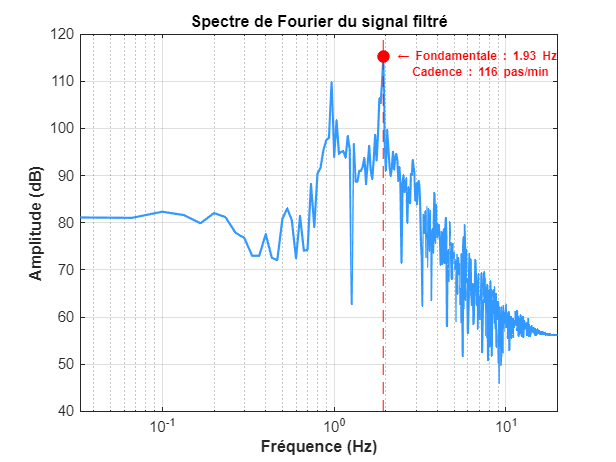


% === TRAITEMENT FFT DU SIGNAL FILTRÉ ===
signal = accFiltered - mean(accFiltered);  % Suppression de la composante DC
N = length(signal);
Y = fft(signal);
f = (0:N-1)*(fs/N);  % Vecteur des fréquences
f_half = f(1:floor(N/2));
Y_half = abs(Y(1:floor(N/2)));

% === DÉTECTION DE LA FRÉQUENCE FONDAMENTALE (ZONE 0.5–5 Hz) ===
f_min = 0.5; 
f_max = 5;
idx_range = (f_half >= f_min & f_half <= f_max);
[~, idx_local] = max(Y_half(idx_range));
idx_global = find(idx_range); 
idx_global = idx_global(idx_local);
fondamentale_freq = f_half(idx_global);

% === CALCUL DE LA CADENCE EN PAS PAR MINUTE ===
cadence = fondamentale_freq * 60;

% === AFFICHAGE DU SPECTRE EN dB AVEC ANNOTATIONS ===
figure;
semilogx(f_half, 20*log10(Y_half), 'LineWidth', 1.5, 'Color', [0.2 0.6 1]); 
hold on;

% Mise en valeur de la fréquence fondamentale
amp_db = 20*log10(Y_half(idx_global));
plot(fondamentale_freq, amp_db, 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r');
xline(fondamentale_freq, '--r', 'LineWidth', 1);

% Annotation texte
text(fondamentale_freq + 0.1, amp_db + 3, ...
    sprintf('\n\n\n \\leftarrow Fondamentale : %.2f Hz\n    Cadence : %.0f pas/min', ...
    fondamentale_freq, cadence), ...
    'FontSize', 8, 'FontWeight', 'bold', 'Color', 'r');

% Axes et style
xlabel('Fréquence (Hz)', 'FontWeight', 'bold');
ylabel('Amplitude (dB)', 'FontWeight', 'bold');
title('Spectre de Fourier du signal filtré', 'FontSize', 12, 'FontWeight', 'bold');
grid on;
xlim([0 fs/2]);
ylim auto;
set(gca, 'FontSize', 10);